## This notebook is to exemplify the use of ruleBasedSelectionHH() class to create single heuristics

## Cleanup

clc
clear
close all


## Load required packages

addpath(genpath('extended/Domains/JSSP')); % Adds JSSP functionality
addpath(genpath('extended/Utils')); % Adds assorted utilities

## Load instances for testing

% ------ First set of training instances (5x5)
instanceDataset = '../../BaseInstances/JobShopScheduling/files/mat/Instances/E02/instanceDataset.mat';
load(instanceDataset);
trainInstances1 = num2cell(allInstances); % Stores instances as cell array

% ------ Second set of training instances (15x15)
instanceDataset = '../../BaseInstances/JobShopScheduling/files/mat/Instances/E01/instanceDataset.mat';
load(instanceDataset);
trainInstances2 = num2cell(allInstances); % Stores as cell array

**First let's create a single HH with only 1 rule and assigning the JSSP domain: **

nbRules=1; 
targetProblem='job shop scheduling'

targetProblem = 'job shop scheduling'

H1=ruleBasedSelectionHH(nbRules,targetProblem)

H1 = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 373)
  In matlab.internal.editor/OutputPackager/isolatedDisplaying
  In matlab.internal.editor/OutputPackager/getStringFromVar
  In matlab.internal.editor/OutputPackager/getTruncatedStringFromVar
  In matlab.internal.editor/OutputPackager/packageVarOther
  In matlab.internal.editor/OutputPackager/packageVar
  In matlab.internal.editor/OutputPackager/packageOneOutput
  In matlab.internal.editor/OutputPackager/packageEachOutput
  In matlab.internal.editor/OutputPackager/packageOutputs
  In matlab.internal.editor/EvaluationOutputsService/outputStreamEvent
  In matlab.internal.editor.EvaluationOutputsService>@(src,ev)

**By creating a HH with single rule we actually create a Heuristic, but it is a random heuristic from the available pool. Let´s try to change the model manually:**

userModel=[1 1 1 1 1 1]

userModel =      1     1     1     1     1     1


H1.value=userModel

H1 = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 373)
  In matlab.internal.editor/OutputPackager/isolatedDisplaying
  In matlab.internal.editor/OutputPackager/getStringFromVar
  In matlab.internal.editor/OutputPackager/getTruncatedStringFromVar
  In matlab.internal.editor/OutputPackager/packageVarOther
  In matlab.internal.editor/OutputPackager/packageVar
  In matlab.internal.editor/OutputPackager/packageOneOutput
  In matlab.internal.editor/OutputPackager/packageEachOutput
  In matlab.internal.editor/OutputPackager/packageOutputs
  In matlab.internal.editor/EvaluationOutputsService/outputStreamEvent
  In matlab.internal.editor.EvaluationOutputsService>@(src,ev)

**Although the model has 5 usable features and 4 usable solvers, we input manually the model. So whenever we solve a problem with this HH it with solve it only with heuristic 1 (corresponding to LPT). **

**We can always reinitialize the model (this requires the number of features and number of solvers) :**

nbFeatures=4;
nbSolvers=3;
H1.initializeModel(nbRules,nbFeatures,nbSolvers)
H1

H1 = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 373)
  In matlab.internal.editor/OutputPackager/isolatedDisplaying
  In matlab.internal.editor/OutputPackager/getStringFromVar
  In matlab.internal.editor/OutputPackager/getTruncatedStringFromVar
  In matlab.internal.editor/OutputPackager/packageVarOther
  In matlab.internal.editor/OutputPackager/packageVar
  In matlab.internal.editor/OutputPackager/packageOneOutput
  In matlab.internal.editor/OutputPackager/packageEachOutput
  In matlab.internal.editor/OutputPackager/packageOutputs
  In matlab.internal.editor/EvaluationOutputsService/outputStreamEvent
  In matlab.internal.editor.EvaluationOutputsService>@(src,ev)

**Now let's make LPT (again) and SPT: **

nbRules=1; 
targetProblem='job shop scheduling';

LPT=ruleBasedSelectionHH(nbRules,targetProblem);

SPT=ruleBasedSelectionHH(nbRules,targetProblem);


LPTmodel=[1 1 1 1 1 1];
SPTmodel=[1 1 1 1 1 2];

LPT.value=LPTmodel

LPT = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 373)
  In matlab.internal.editor/OutputPackager/isolatedDisplaying
  In matlab.internal.editor/OutputPackager/getStringFromVar
  In matlab.internal.editor/OutputPackager/getTruncatedStringFromVar
  In matlab.internal.editor/OutputPackager/packageVarOther
  In matlab.internal.editor/OutputPackager/packageVar
  In matlab.internal.editor/OutputPackager/packageOneOutput
  In matlab.internal.editor/OutputPackager/packageEachOutput
  In matlab.internal.editor/OutputPackager/packageOutputs
  In matlab.internal.editor/EvaluationOutputsService/outputStreamEvent
  In matlab.internal.editor.EvaluationOutputsService>@(src,ev

SPT.value=SPTmodel

SPT = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 373)
  In matlab.internal.editor/OutputPackager/isolatedDisplaying
  In matlab.internal.editor/OutputPackager/getStringFromVar
  In matlab.internal.editor/OutputPackager/getTruncatedStringFromVar
  In matlab.internal.editor/OutputPackager/packageVarOther
  In matlab.internal.editor/OutputPackager/packageVar
  In matlab.internal.editor/OutputPackager/packageOneOutput
  In matlab.internal.editor/OutputPackager/packageEachOutput
  In matlab.internal.editor/OutputPackager/packageOutputs
  In matlab.internal.editor/EvaluationOutputsService/outputStreamEvent
  In matlab.internal.editor.EvaluationOutputsService>@(src,ev

**Now that we have two heuristics created with the ruleBasedSelectionHH() let's solve some instances: **

solvedInstances_LPT = LPT.solveInstanceSet(trainInstances1)

solvedInstances_LPT = 1×30 cell array
    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}


solvedInstances_SPT=SPT.solveInstanceSet(trainInstances1)

solvedInstances_SPT = 1×30 cell array
    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}


**Let's visualize the performance of the first Instances for both solvers: **

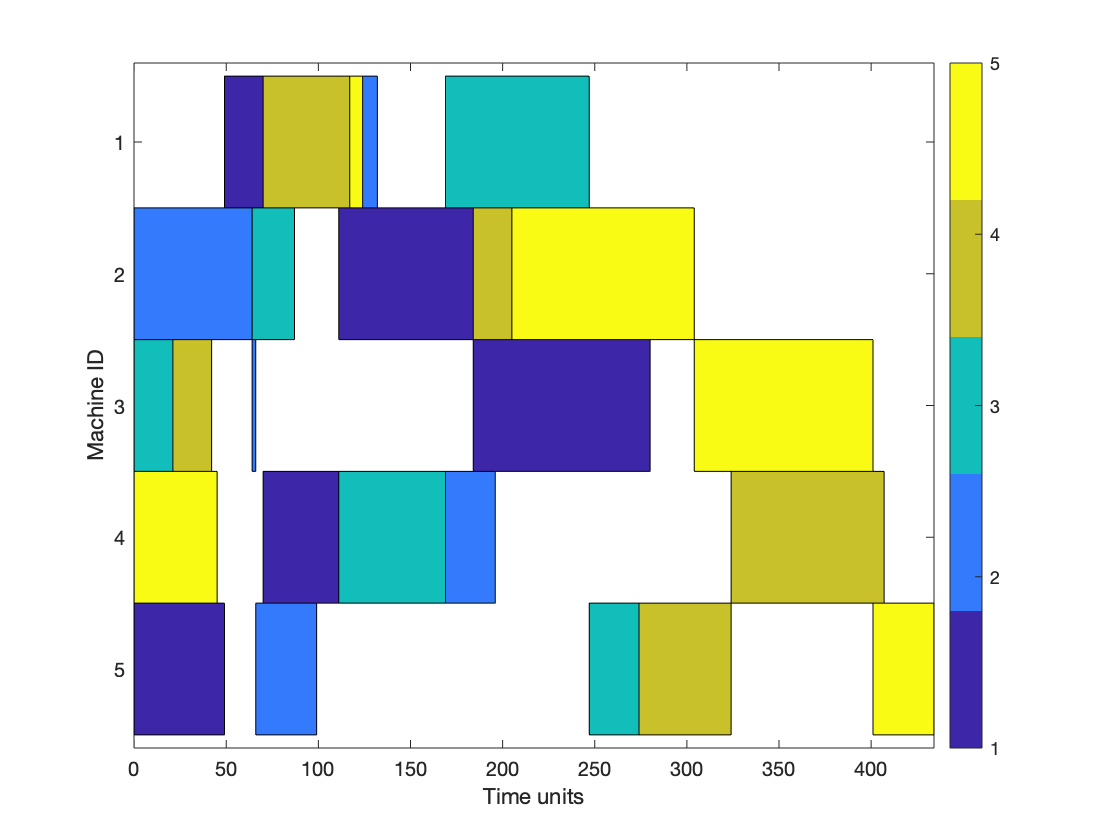

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 7
        Name: ''
       Color: [1 1 1]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


LPT.performanceData{1}{end}.solution.plot

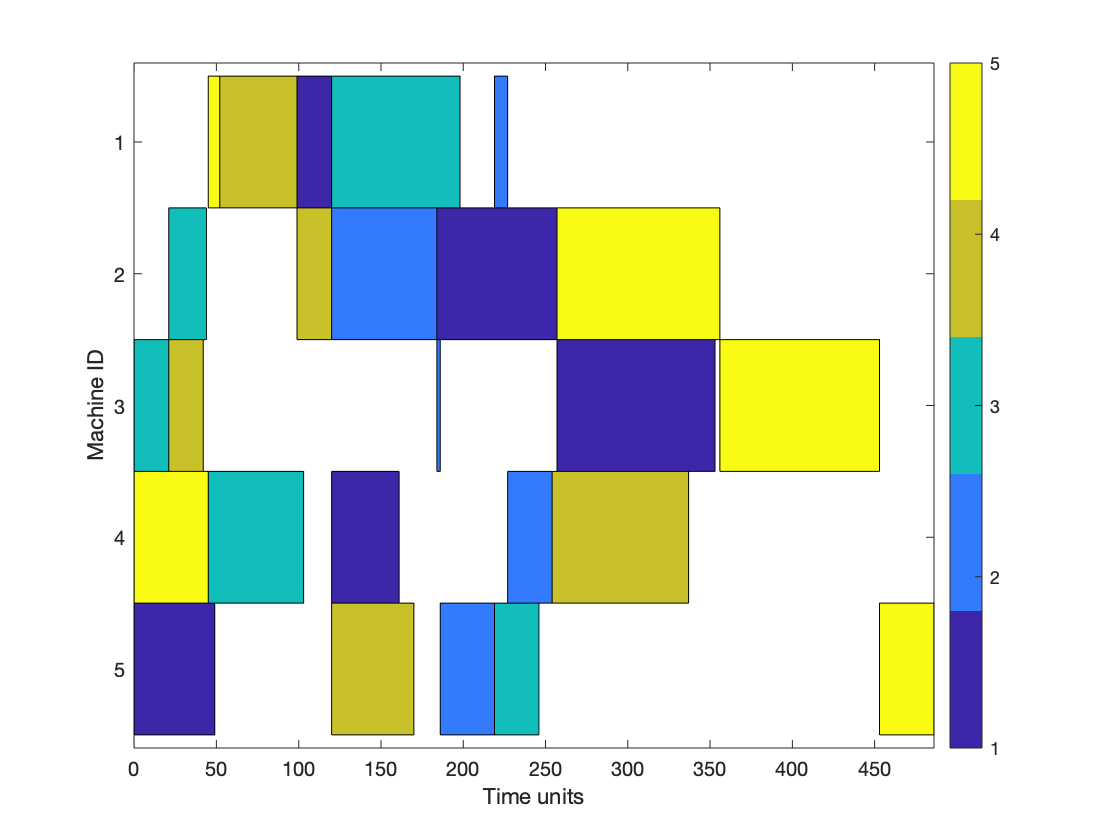

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 8
        Name: ''
       Color: [1 1 1]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


SPT.performanceData{1}{end}.solution.plot

**With these plots we can easily see that the first instance from trainInstances1 is better solved by LPT **